clear all
clc
close all


I1 = imread(['Flecha.png']);
NumPix = size(I1, 1) * size(I1, 2)

NumPix = 2500

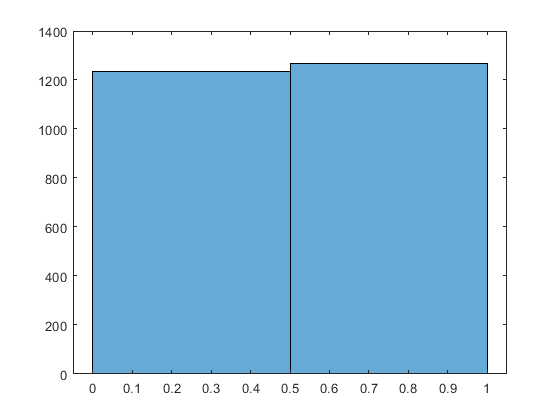

BW = im2bw(I1,0.9);
histogram(BW,2)

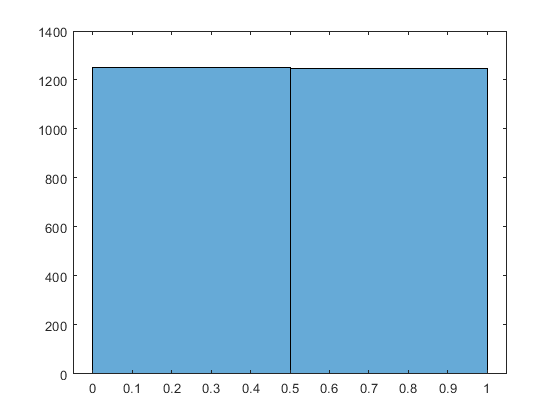

%imshow(BW);
Flecha=reshape(BW',[1,NumPix])';

I2 = imread(['Cinco.png']);
BW = im2bw(I2,0.9);
histogram(BW,2)

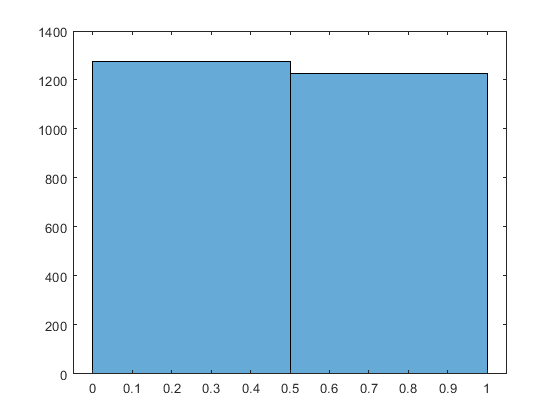

%imshow(BW);
Cinco=reshape(BW',[1,NumPix])';

I3 = imread(['Mas.png']);
BW = im2bw(I3,0.9);
histogram(BW,2)

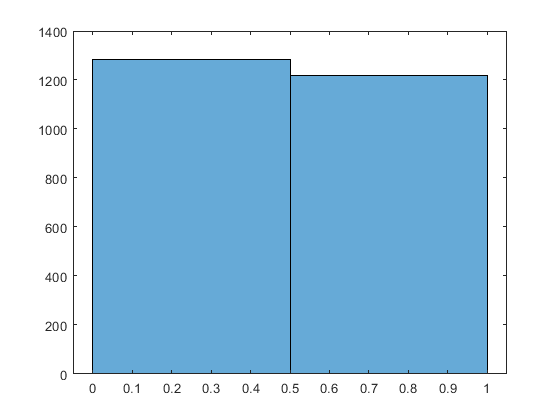

%imshow(BW);
Mas=reshape(BW',[1,NumPix])';

I4 = imread(['Nueve.png']);
BW = im2bw(I4,0.9);
histogram(BW,2)

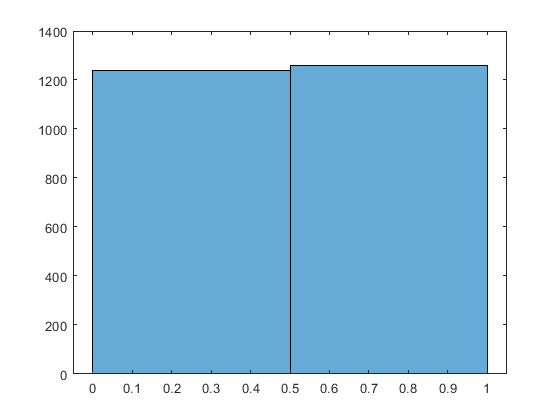

%imshow(BW);
Nueve=reshape(BW',[1,NumPix])';

I5 = imread(['Cero.png']);
BW = im2bw(I5,0.9);
histogram(BW,2)

%imshow(BW);
Cero=reshape(BW',[1,NumPix])';

I6 = imread(['Ele.png']);
BW = im2bw(I6,0.9);
histogram(BW,2)

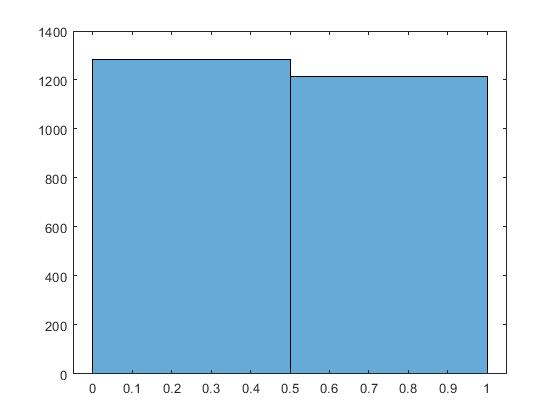

%imshow(BW);
Ele=reshape(BW',[1,NumPix])';

I7 = imread(['Erre.png']);
BW = im2bw(I7,0.9);
histogram(BW,2)

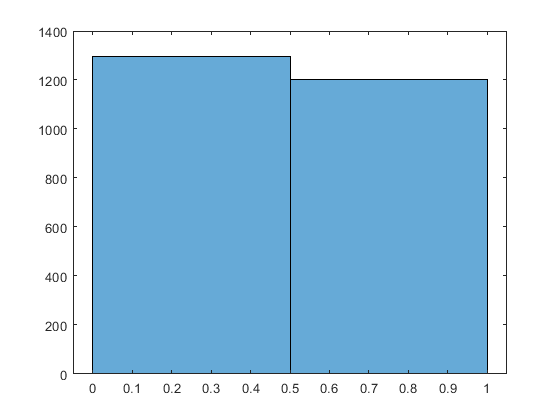

%imshow(BW);
Erre=reshape(BW',[1,NumPix])';

I8 = imread(['Uno.png']);
BW = im2bw(I8,0.9);
histogram(BW,2)

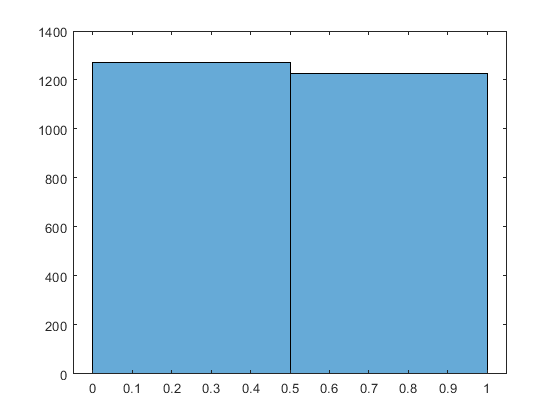

%imshow(BW);
Uno=reshape(BW',[1,NumPix])';

I9 = imread(['Mayor.png']);
BW = im2bw(I9,0.9);
histogram(BW,2)

%imshow(BW);
Mayor=reshape(BW',[1,NumPix])';

I10 = imread(['X.png']);
BW = im2bw(I10,0.9)

BW = 50×50 logical array
   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   

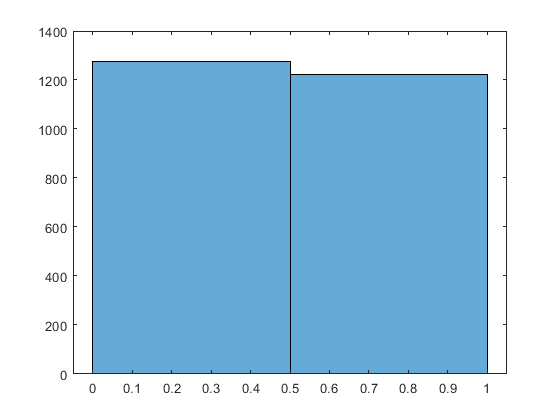

histogram(BW,2)

%imshow(BW);
Equis=reshape(BW',[1,NumPix])';

X=[Uno,Erre,Ele,Cero,Mayor,Flecha,Mas,Cinco,Nueve,Equis];
X=(X.*-2)+1;
W=X*pinv(X)

W =     0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0007   -0.0006   -0.0006   -0.0006   -0.0001   -0.0001   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0014   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007
    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0007   -0.0006   -0.0006   -0.0006   -0.0001   -0.0001   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0014   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0


Xp=Uno;

% while true
% S=W*Xp;
% Y=sign(S);
% 
% for i=1:size(Xp,1)
%     for j=1:size(Xp,2)
%        if Y==0
%            Y(i,j)=Xp(i,j);
%        end
%     end
% end
% Xp=Y;
% C=reshape(Xp, [sqrt(NumPix),sqrt(NumPix)])';
% imshow(C);
% drawnow limitrate
% end